# Base de dados da aeronáutica

Trata-se de *web scraping* do portal AISWEB - [https://aisweb.decea.mil.br](https://aisweb.decea.mil.br) -, extraindo informações dos canais de radionavegação e comunicação em uso no entorno dos principais aeroportos do país. Destacados com fundo amarelo os valores de frequência dos diversos sistemas (ILS, VOR e NDB, por exemplo) - para o sistema NDB, a frequência é em "kHz"; para todos os outros, em "MHz".

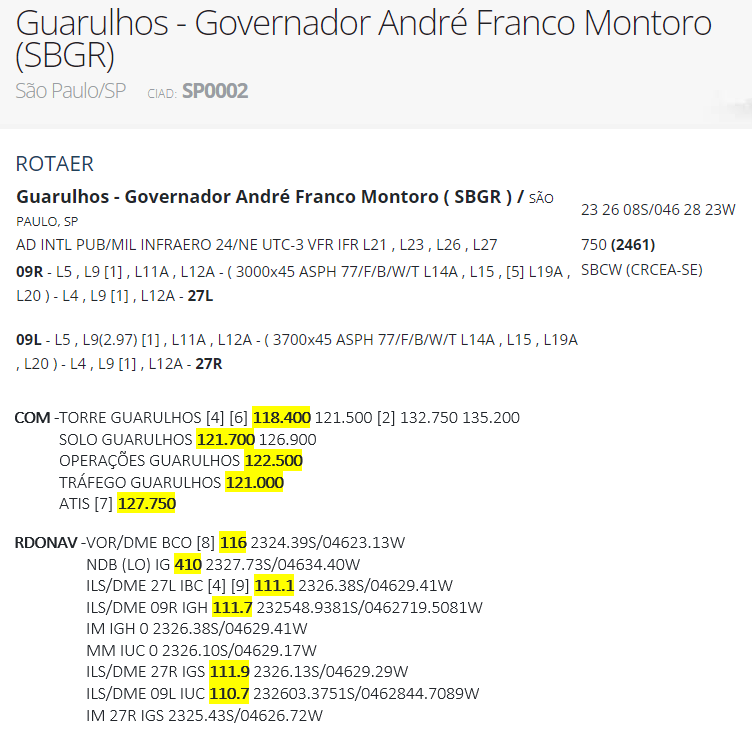

O endereço base das páginas que apresentam essas informações é [https://aisweb.decea.mil.br/?i=aerodromos&codigo=SBSV](https://aisweb.decea.mil.br/?i=aerodromos&codigo=SBSV), com a ressalva que os últimos quatro algarismos correspondem ao código ICAO do aeródromo.

A seguir tela extraída do portal AISWEB que possibilitou a criação de base de dados que relacione os aeródromos e os seus códigos ICAO. Para tanto, foram aplicados os seguintes filtros:

- Campo "Tipo": "AD" (aeródromo); e

- Campo "Utilização": "MIL", "PRIV/PUB", "PUB", "PUB/MIL" e "PUB/REST". 

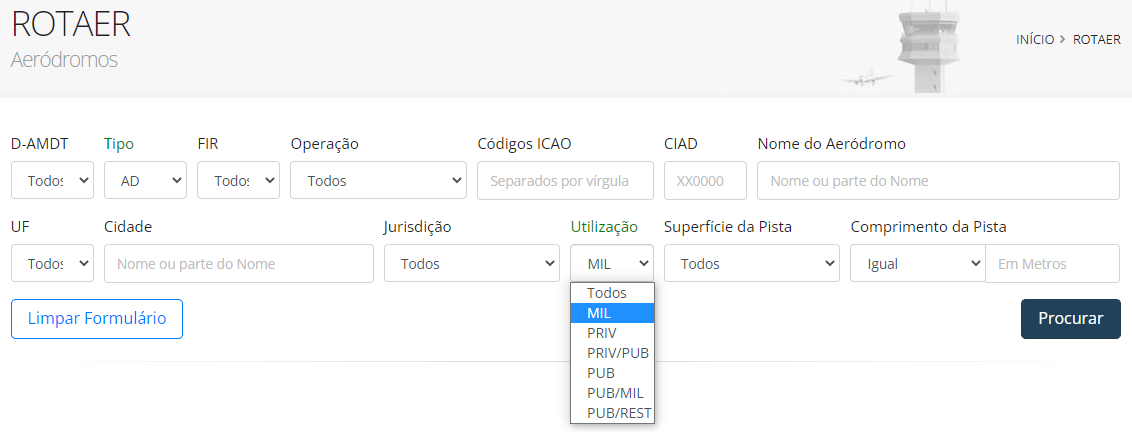

Por fim, faz-se o mapeamento dos canais relacionadas ao VOR e ILS *localizer* apresentados no portal AISWEB com a tabela de canalização dos sistemas VOR, ILS e DME. Isto é necessário porque a aeronáutica, de forma geral, registra apenas a frequência central do canal em 108-118 MHz. Os canais relacionados ao *Airbone* DME, ressalte-se, não são passíveis de licenciamento pela aeronáutica por se tratar de sistemas embarcados nas aeronaves.

- VOR e ILS *localizer*: 108:.05:117.95

- ILS *glide path*: [311.4, 329.15:.15:335]

- *Airbone* DME: 1025:1147

- *Ground-base* DME: 962:1213

Versão: **09/02/2022**

function [RotaerDB, RotaerDB_ExtractDate] = Misc_Aisweb(RootFolder, AirportSheet)

    arguments
        RootFolder   char
        AirportSheet char = '20220127 - ICAO Airports.xlsx'
    end

    RotaerDB = table('Size', [0, 6],                                                            ...
                     'VariableTypes', {'single', 'single', 'single', 'cell', 'int16', 'int32'}, ...
                     'VariableNames', {'Frequency', 'Latitude', 'Longitude', 'Description', 'Service', 'Station'});

    Tag1 = sprintf('<table border="0" cellpadding="0">\n<tr>\n<td valign="top">RDONAV - </td>');
    Tag2 = sprintf('<table border="0" cellpadding="0">\n<tr>\n<td valign="top">COM - </td>');
    Tag3 = '</table>';

    icaoTab = readtable(fullfile(RootFolder, 'DataBase', AirportSheet));
    icaoTab.Latitude  = single(icaoTab.Latitude);
    icaoTab.Longitude = single(icaoTab.Longitude);

    for ii = 1:height(icaoTab)
        if ~icaoTab.Flag(ii)
            continue
        end
%         ii/height(icaoTab)

        try
            kk = 0;
            while true
                try
                    aisWeb = webread(sprintf('https://aisweb.decea.mil.br/?i=aerodromos&codigo=%s', icaoTab.ICAO{ii}), weboptions('Timeout', 5));
                    break
                catch ME
                    kk = kk+1;
                    pause(1)
    
                    if kk == 3; error(ME.message)
                    end
                end
            end

            % Airport info (struct)
            Airport.name      = deblank(char(extractBetween(aisWeb, '<span title="Nome do Aeródromo">', '</span>')));
            Airport.ICAO      = extractBetween(aisWeb, '<span title="Indicador de Localidade (ICAO Code)">', '</span>');
            Airport.Latitude  = icaoTab.Latitude(ii);
            Airport.Longitude = icaoTab.Longitude(ii);
            Airport.City      = icaoTab.gpsCity{ii};
    
            % HTML tables to read
            htmlCell = [extractBetween(aisWeb, Tag1, Tag3, 'Boundaries', 'inclusive'); ...
                        extractBetween(aisWeb, Tag2, Tag3, 'Boundaries', 'inclusive')];
    
            if ~isempty(htmlCell)
                icaoTab.Flag(ii) = 1;
                
                matTab = Fcn_html2matTable(htmlCell, Airport);
                RotaerDB(end+1:end+height(matTab),:) = matTab;
            else
                icaoTab.Flag(ii) = 0;
            end

        catch ME
            fprintf('%s: %s\n', sprintf('https://aisweb.decea.mil.br/?i=aerodromos&codigo=%s', icaoTab.ICAO{ii}), ME.message)

            icaoTab.Flag(ii) = -1;
            continue
        end
    end
    RotaerDB = Misc_ChannelMap(RotaerDB);
    RotaerDB = Misc_AnatelDBQuery(RotaerDB);
    
    RotaerDB_ExtractDate = datestr(now, 'dd/mm/yyyy HH:MM:SS');

    writetable(icaoTab, fullfile(RootFolder, 'DataBase', AirportSheet))
    
end

function matTab = Fcn_html2matTable(htmlCell, Airport)

    matTab = table('Size', [0, 6],                                                            ...
                   'VariableTypes', {'single', 'single', 'single', 'cell', 'int16', 'int32'}, ...
                   'VariableNames', {'Frequency', 'Latitude', 'Longitude', 'Description', 'Service', 'Station'});

    for ii = 1:numel(htmlCell)
        if contains(htmlCell{ii}, 'RDONAV')
            Type = 'RDONAV';
        else
            Type = 'COM';
        end

        tempCell = extractBetween(htmlCell{ii}, '<div>', '</div>');

        for jj = 1:numel(tempCell)
            splitCell = splitlines(tempCell{jj});
            
            splitCell(cellfun(@(x) isempty(x), splitCell))          = [];
            splitCell(cellfun(@(x) contains(x, 'span'), splitCell)) = [];

            % Latitude/longitude info
            [splitCell, Latitude, Longitude] = Fcn_SystemCoordinatesRead(splitCell, Airport);

            % Subtype and frequency info
            idx = isnan(str2double(splitCell));

            Subtype   = deblank(strjoin(splitCell(idx)));
            Frequency = str2double(splitCell(~idx));

            if ~isempty(Frequency) & Frequency
                Description = sprintf('[AIS] %s-%s, %s, %s', Airport.ICAO{1}, Type, ...
                                                             Subtype, Airport.name);

                matTab(end+1:end+height(Frequency),:) = [num2cell(Frequency),                         ...
                                                         repmat({Latitude},    height(Frequency), 1), ...
                                                         repmat({Longitude},   height(Frequency), 1), ...
                                                         repmat({Description}, height(Frequency), 1), ...
                                                         num2cell(-ones(height(Frequency), 1)), num2cell(-ones(height(Frequency), 1))];
            end
        end
    end
end


function [splitCell, Latitude, Longitude] = Fcn_SystemCoordinatesRead(splitCell, Airport)

    Coordinates = cellfun(@(x) char(regexp(x, '\d{4}.\d{2}[SN]/\d{5}.\d{2}[EW]', 'match')), splitCell, 'UniformOutput', false);
    idx1        = cellfun(@(x) isempty(x), Coordinates);
    Coordinates = char(Coordinates(~idx1));

    if ~isempty(Coordinates)
        CoordinatesType = 1;
    else
        CoordinatesType = 2;

        Coordinates = cellfun(@(x) char(regexp(x, '\d{6}.\d{4}[SN]/\d{7}.\d{4}[EW]', 'match')), splitCell, 'UniformOutput', false);
        idx1        = cellfun(@(x) isempty(x), Coordinates);
        Coordinates = char(Coordinates(~idx1));
    end

    if ~isempty(Coordinates)
        splitCell   = replace(splitCell, Coordinates, '');
        Coordinates = strsplit(Coordinates, '/');

        switch CoordinatesType
            case 1
                Latitude  = str2double(Coordinates{1}(1:2)) + str2double(Coordinates{1}(3:end-1))/60;
                Longitude = str2double(Coordinates{2}(1:3)) + str2double(Coordinates{2}(4:end-1))/60;

            case 2
                Latitude  = str2double(Coordinates{1}(1:2)) + str2double(Coordinates{1}(3:4))/60 + str2double(Coordinates{1}(5:end-1))/3600;
                Longitude = str2double(Coordinates{2}(1:3)) + str2double(Coordinates{2}(4:5))/60 + str2double(Coordinates{2}(6:end-1))/3600;
        end
        
        if Coordinates{1}(end) == 'S'; Latitude = -Latitude;
        end
        
        if Coordinates{2}(end) == 'W'; Longitude = -Longitude;
        end

    else
        Latitude  = Airport.Latitude;
        Longitude = Airport.Longitude;
    end

end